# Transfer fucntion derivation based on experiments

####  Bring our recorded data into a Bode-plot

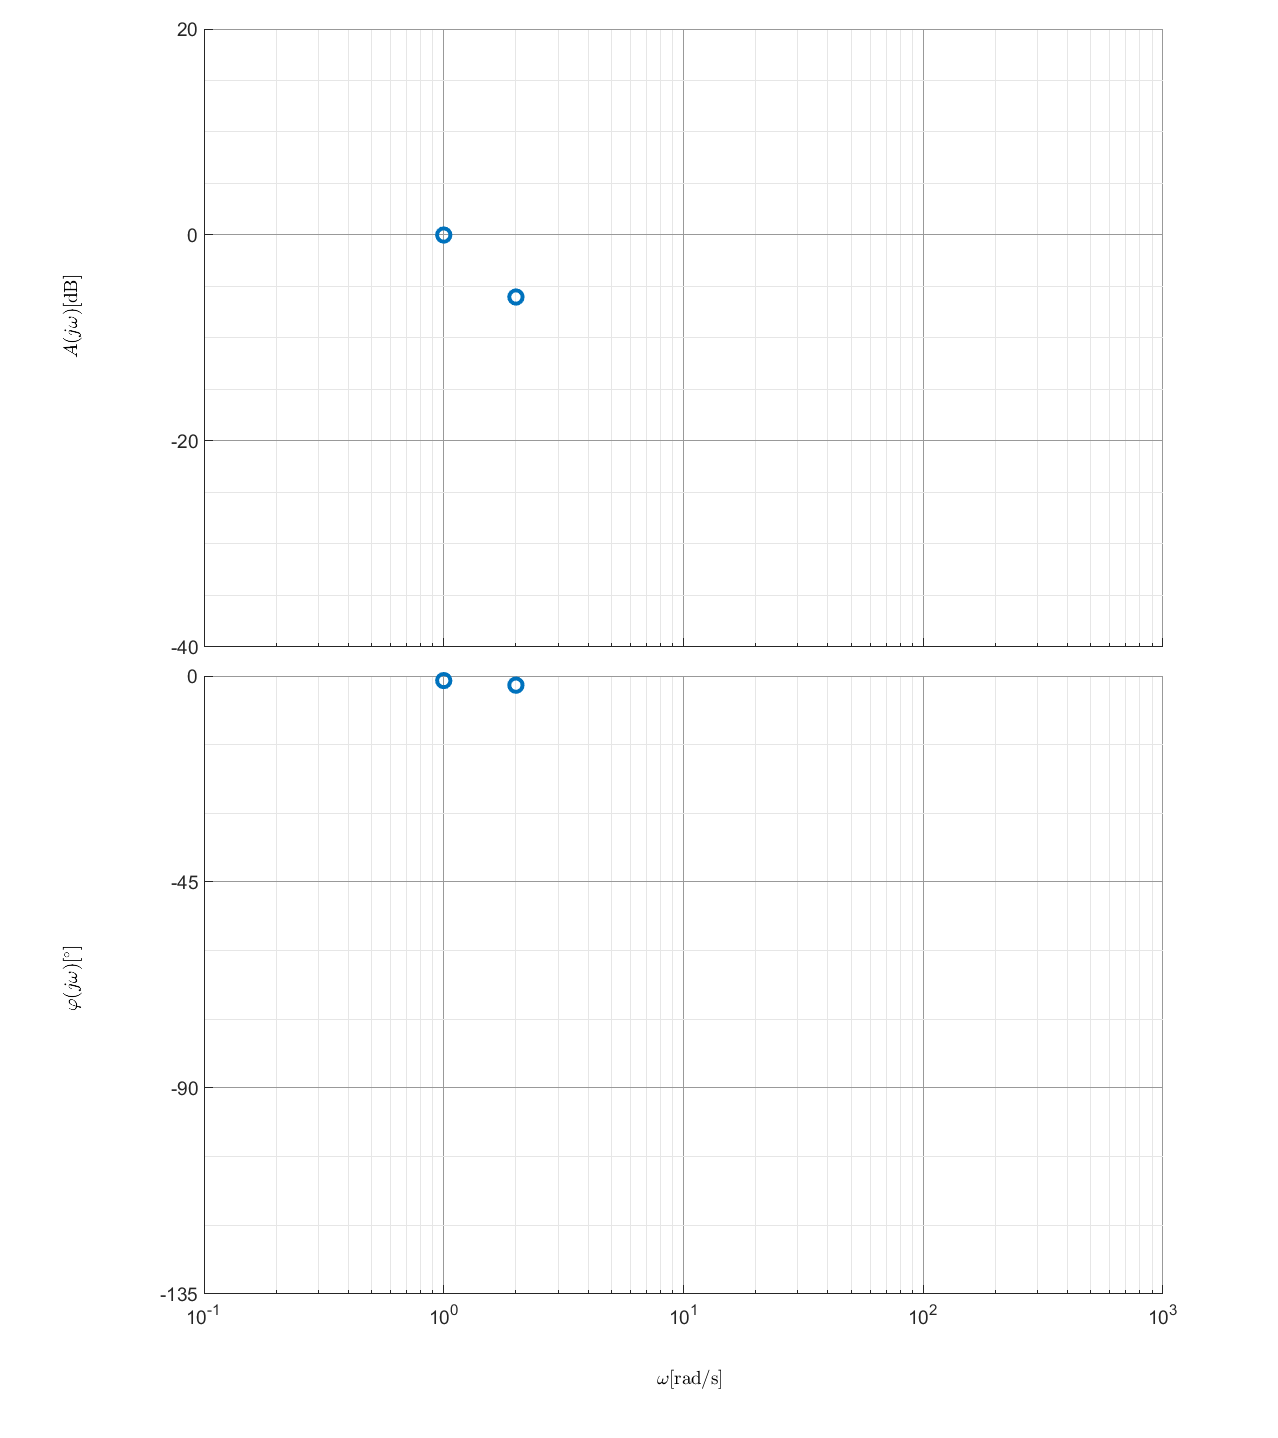

% plot own measurement data; replace the dummy values in the vectors below with your data, where
% w..Omega (angular frequency)
% a..Amplitude Gain (absolute or in dB, adjust call to plot accordingly)
% p..phase shift (in degree)
w = [1 2]; 
a = [1 0.5];
p = [-1 -2];

%% open new bode plot and save axes for magnitude and phase plot
[am ph]=nn_bode_blank([-1 3],[-40 20],[-135 0]);
%plot
axes(am);plot(w,20*log10(a),'o','Markersize',10,'Linewidth',3);
axes(ph);plot(w,p,'o','Markersize',10,'Linewidth',3);

#### If your points match with the points on your working sheet, you can try to fit the data

% Use the system behavior you analyzed from the Bode plot and generate a transfer function G.
% I tried a PT1 but it is obviously wrong. I hope you can do better!
% You need to
% (i) generate the transfer function G  based on the system behavior you derived on paper
% (ii) change the numerical value until the fit looks okay(ish)!
G = 1/(s+1)


G =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.



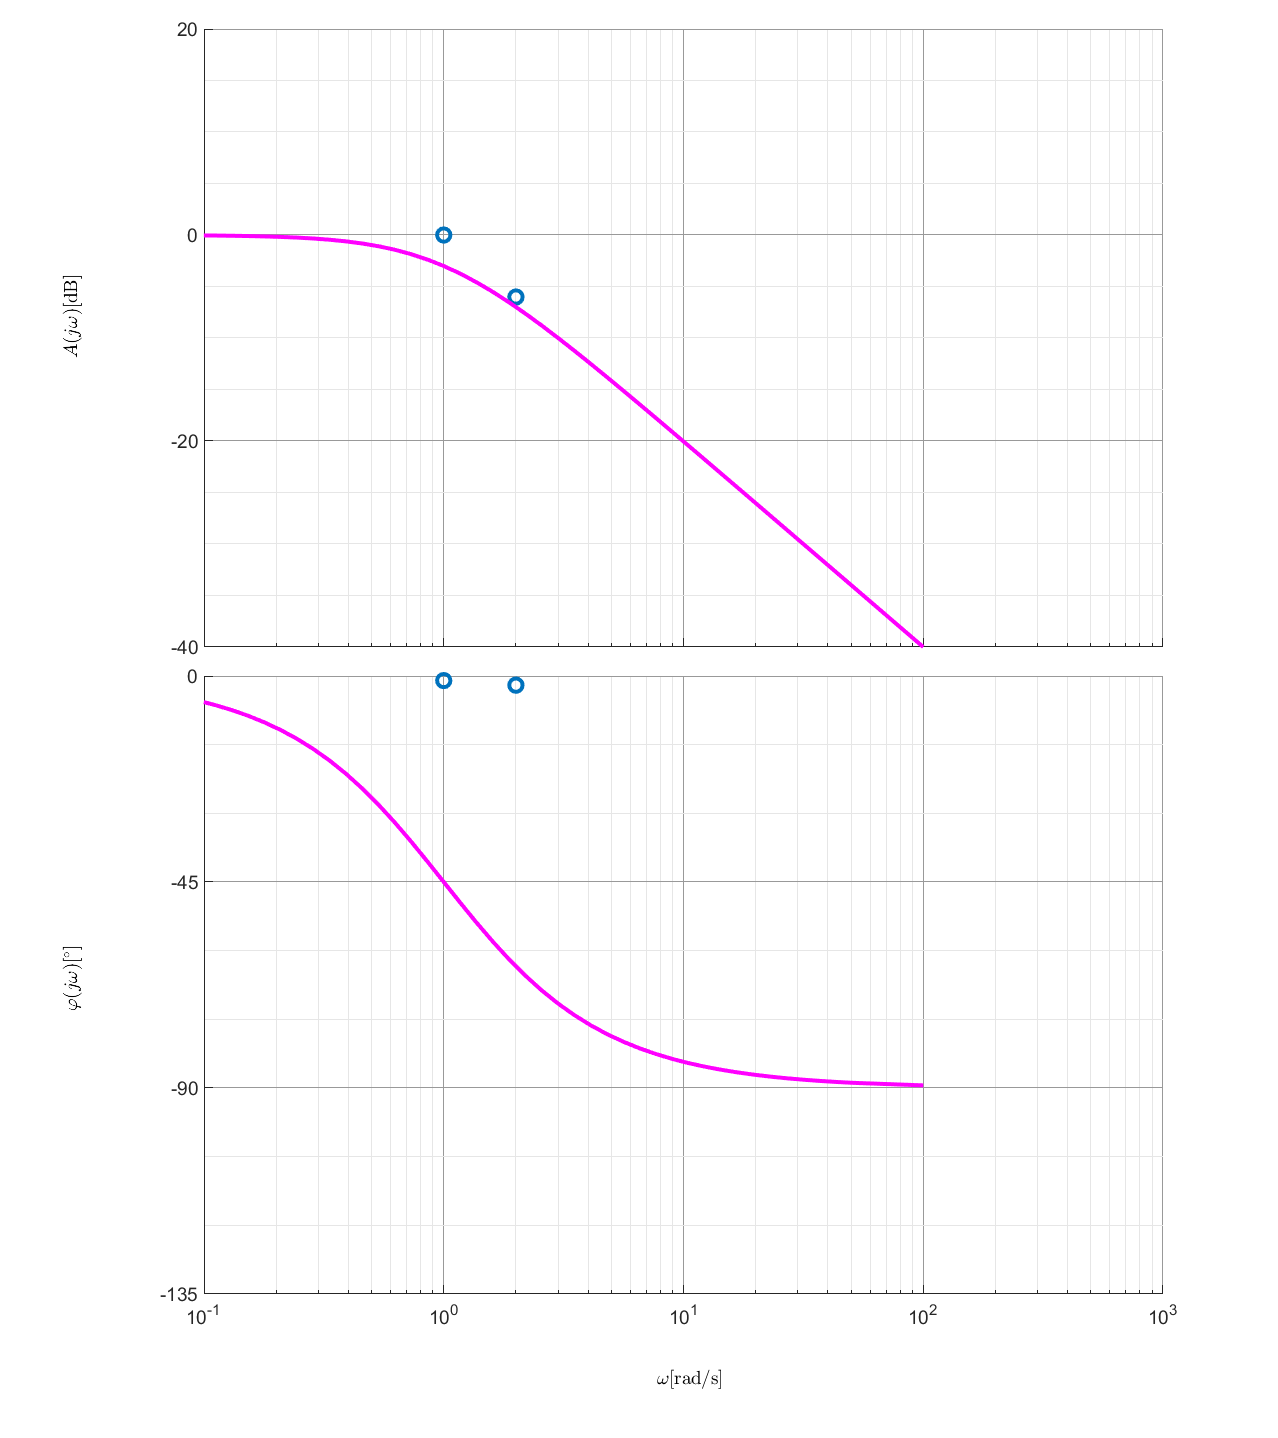

% Plot the Bode diagram for the system
[am ph]=nn_bode_blank([-1 3],[-40 20],[-135 0]);
axes(am);plot(w,20*log10(a),'o','Markersize',10,'Linewidth',3);
axes(ph);plot(w,p,'o','Markersize',10,'Linewidth',3);
nn_bode(G)
hold on